function out = omni_procesar_imagen(imgPath, calibPath, maskPath, opts)
% Procesa UNA imagen: segmenta con máscara, undistort y reconstruye panorama.
% - calibPath: cameraParams (.mat o .yml)
% - maskPath : máscara (.mat con mask_ref o pos/rad, o .yml con mascaraRes_WxH)
%
% opts (opcionales):
%   nTheta         (720)   ancho de panorama
%   rMinFraction   (0.06)  recorte interior (evita zona del pinhole)
%   thetaOffsetDeg (0)     giro azimutal (desplaza columnas)
%   flip180        (true)  rotar 180° al final (sin reinterpolar)
%   sigma          (0.0)   suavizado gauss en el panorama
%   show           (true)  mostrar figura
%   saveDir        ('')    si no es vacío, guarda _masked, _und, _pano

    if nargin < 4, opts = struct(); end
    if ~isfield(opts,'nTheta'),         opts.nTheta = 720; end
    if ~isfield(opts,'rMinFraction'),   opts.rMinFraction = 0.06; end
    if ~isfield(opts,'thetaOffsetDeg'), opts.thetaOffsetDeg = 0; end
    if ~isfield(opts,'flip180'),        opts.flip180 = true; end
    if ~isfield(opts,'sigma'),          opts.sigma = 0.0; end
    if ~isfield(opts,'show'),           opts.show = true; end
    if ~isfield(opts,'saveDir'),        opts.saveDir = ''; end

    I = imread(imgPath);
    [H,W,~] = size(I);

    % --- Cargar calibración ---
    cam = load_camera_any(calibPath);
    Hc = cam.ImageSize(1); Wc = cam.ImageSize(2);
    assert(H==Hc && W==Wc, 'La imagen (%dx%d) no coincide con la calibración (%dx%d).', W,H,Wc,Hc);

    % --- Cargar máscara (dominio distorsionado) ---
    M = load_mask_any(maskPath, [H W]);

    % --- Aplicar máscara en imagen distorsionada ---
    Im = I;
    if size(Im,3)==1
        Im(~M) = 0;
    else
        Im(repmat(~M,[1 1 size(Im,3)])) = 0;
    end

    % --- Undistort de imagen y máscara ---
    Iu   = undistortImage(Im,          cam, 'OutputView','same');
    Mund = undistortImage(single(M),   cam, 'OutputView','same') > 0.5;
    Mund = bwareafilt(Mund,1);

    % --- Centro y radio (círculo máximo inscribible) ---
    D = bwdist(~Mund);
    [rMax0, idx] = max(D(:));
    [cy, cx] = ind2sub(size(Mund), idx);
    rMin = max(2, round(opts.rMinFraction * rMax0));
    rMax = max(rMin+5, floor(rMax0)-2);

    % --- Unwrap (polar -> cartesiano) ---
    nTheta = opts.nTheta;
    nR = rMax - rMin + 1;
    [TH, R] = meshgrid(linspace(0,2*pi,nTheta), linspace(rMin, rMax, nR));
    X = cx + R .* cos(TH);
    Y = cy + R .* sin(TH);

    pano = zeros(nR, nTheta, size(Iu,3), 'uint8');
    for c = 1:size(Iu,3)
        pano(:,:,c) = uint8(interp2(double(Iu(:,:,c)), X, Y, 'cubic', 0));
    end

    % Desplazamiento de azimut (opcional) y rotación 180° (para ver “derecho”)
    if opts.thetaOffsetDeg ~= 0
        pano = circshift(pano, [0, round((opts.thetaOffsetDeg/360)*nTheta), 0]);
    end
    if opts.flip180, pano = rot90(pano, 2); end
    if opts.sigma > 0, pano = imgaussfilt(pano, opts.sigma); end

    % --- Visualización ---
    if opts.show
        figure('Name','Omni: máscara -> undistort -> panorama');
        tiledlayout(2,3,'Padding','compact','TileSpacing','compact');
        nexttile; imshow(I);  title('Original');
        nexttile; imshow(M);  title('Máscara');
        nexttile; imshow(Im); title('Segmentada');
        nexttile; imshow(Iu); title('Sin distorsión');
        nexttile; imshow(labeloverlay(Iu, Mund)); title('ROI undistort');
        nexttile; imshow(pano); title('Panorámica');
    end

    % --- Guardado opcional ---
    if ~isempty(opts.saveDir)
        if ~exist(opts.saveDir,'dir'), mkdir(opts.saveDir); end
        [~,name,~] = fileparts(imgPath);
        imwrite(Im,   fullfile(opts.saveDir, [name '_masked.png']));
        imwrite(Iu,   fullfile(opts.saveDir, [name '_und.png']));
        imwrite(pano, fullfile(opts.saveDir, [name '_pano.png']));
    end

    % --- Salida ---
    out = struct('I',I,'M',M,'Im',Im,'Iu',Iu,'Mund',Mund, ...
                 'cx',cx,'cy',cy,'rMin',rMin,'rMax',rMax,'pano',pano,'cam',cam);
end

% ========================= HELPERS =========================

function cam = load_camera_any(path)
    [~,~,ext] = fileparts(path);
    switch lower(ext)
        case '.mat'
            S = load(path);
            assert(isfield(S,'cameraParams'),'El .mat no contiene "cameraParams".');
            cam = S.cameraParams;
        case {'.yml','.yaml'}
            cam = build_camera_from_yaml(path);
        otherwise
            error('Formato de calibración no soportado: %s', ext);
    end
end

function M = load_mask_any(path, imageSize)
% Devuelve máscara binaria del tamaño 'imageSize' en el dominio distorsionado
    H = imageSize(1); W = imageSize(2);
    [~,~,ext] = fileparts(path);
    switch lower(ext)
        case {'.yml','.yaml'}
            M = load_mask_from_yaml(path, imageSize);
        case '.mat'
            S = load(path);
            if isfield(S,'mask_ref')
                mr = logical(S.mask_ref); [Hm,Wm] = size(mr);
                if Hm==H && Wm==W
                    M = mr;
                else
                    if isfield(S,'pos') && isfield(S,'rad')
                        sx=W/Wm; sy=H/Hm;
                        cx=S.pos(1)*sx; cy=S.pos(2)*sy; r=S.rad*min(sx,sy);
                        [X,Y]=meshgrid(1:W,1:H); M=((X-cx).^2+(Y-cy).^2)<=r^2;
                    else
                        M = imresize(mr,[H W],'nearest')>0;
                    end
                end
            elseif isfield(S,'pos') && isfield(S,'rad')
                cx=S.pos(1); cy=S.pos(2); r=S.rad;
                if isfield(S,'imageSize')
                    Hm=S.imageSize(1); Wm=S.imageSize(2);
                    sx=W/Wm; sy=H/Hm; cx=cx*sx; cy=cy*sy; r=r*min(sx,sy);
                end
                [X,Y]=meshgrid(1:W,1:H); M=((X-cx).^2+(Y-cy).^2)<=r^2;
            else
                error('El .mat de máscara no tiene "mask_ref" ni "pos/rad".');
            end
        otherwise
            error('Formato de máscara no soportado: %s', ext);
    end
    M = logical(M);
end

function M = load_mask_from_yaml(ymlPath, imageSize)
    H=imageSize(1); W=imageSize(2);
    key=sprintf('mascaraRes_%dx%d', W, H);
    masks=leer_mascaras_yaml(ymlPath);
    assert(isfield(masks,key), 'No existe %s en %s', key, ymlPath);
    e=masks.(key); [X,Y]=meshgrid(1:W,1:H);
    M=((X-e.center(1)).^2 + (Y-e.center(2)).^2) <= e.radius.^2;
end

function cam = build_camera_from_yaml(ymlPath)
    txt=fileread(ymlPath); rg=@(p)regexp(txt,p,'tokens','once');
    im=rg('imageSize:\s*\[\s*([0-9]+)\s*,\s*([0-9]+)\s*\]'); H=str2double(im{1}); W=str2double(im{2});
    fl=rg('focalLength:\s*\[\s*([0-9eE\+\-\.]+)\s*,\s*([0-9eE\+\-\.]+)\s*\]'); fx=str2double(fl{1}); fy=str2double(fl{2});
    pp=rg('principalPoint:\s*\[\s*([0-9eE\+\-\.]+)\s*,\s*([0-9eE\+\-\.]+)\s*\]'); cx=str2double(pp{1}); cy=str2double(pp{2});
    kr=rg('radialDistortion:\s*\[\s*([^\]]+)\]'); kv=sscanf(kr{1},'%f,'); kv=kv(:)'; if numel(kv)==2, kv(3)=0; end
    tg=rg('tangentialDistortion:\s*\[\s*([^\]]+)\]'); if isempty(tg), pv=[0 0]; else, pv=sscanf(tg{1},'%f,'); pv=pv(:)'; if isempty(pv), pv=[0 0]; end, end
    K=[fx 0 cx; 0 fy cy; 0 0 1];
    cam=cameraParameters('IntrinsicMatrix',K','ImageSize',[H W], ...
                         'RadialDistortion',kv,'TangentialDistortion',pv);
end

function masks = leer_mascaras_yaml(ymlPath)
    txt=fileread(ymlPath); lines=splitlines(txt);
    masks=struct(); in=false; key=''; entry=struct();
    for i=1:numel(lines)
        L=string(lines{i});
        if ~in, if startsWith(strtrim(L),"masks:"), in=true; end; continue; end
        mKey=regexp(L,'^\s{2}([^\s:]+):\s*$','tokens','once');
        if ~isempty(mKey)
            if ~isempty(key), masks.(key)=entry; end
            key=char(mKey{1}); entry=struct(); continue
        end
        mC=regexp(L,'^\s{4}center:\s*\[\s*([0-9eE\+\-\.]+)\s*,\s*([0-9eE\+\-\.]+)\s*\]\s*$','tokens','once');
        if ~isempty(mC), entry.center=[str2double(mC{1}) str2double(mC{2})]; continue, end
        mR=regexp(L,'^\s{4}radius:\s*([0-9eE\+\-\.]+)\s*$','tokens','once');
        if ~isempty(mR), entry.radius=str2double(mR{1}); continue, end
        mS=regexp(L,'^\s{4}imageSize:\s*\[\s*([0-9]+)\s*,\s*([0-9]+)\s*\]\s*$','tokens','once');
        if ~isempty(mS), entry.imageSize=[str2double(mS{1}) str2double(mS{2})]; continue, end
    end
    if ~isempty(key), masks.(key)=entry; end
end

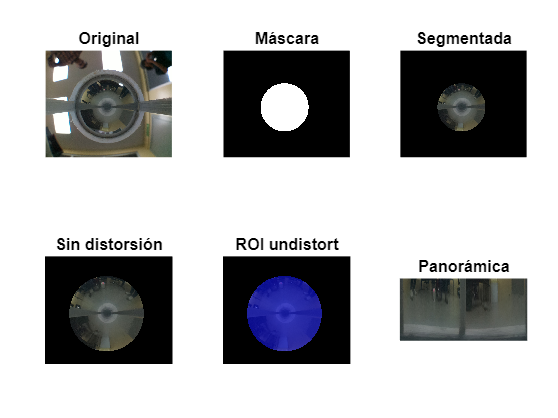

imgPath   = 'C:\Users\GMADRO04\Documents\SOLER\QUPA\Testeo_QUPA\camara_QUPA\img_qupas\img_20250724_145948.jpg';          % tu imagen recién tomada (1280x1080)
% Ejemplos img_20250724_145948 img_20250724_145926
calibPath = 'calib_output/cameraParams_1280x1080.mat';      % o .yml
maskPath  = 'espejo_mask.mat';                              % o 'mascaras.yml'

out = omni_procesar_imagen(imgPath, calibPath, maskPath, ...
      struct('nTheta',720, 'rMinFraction',0.06, ...
             'thetaOffsetDeg',0, 'flip180',true, ...
             'sigma',0.4, 'show',true, 'saveDir',''));